# Script to evaluate the location of the load cells in the vibration prototype fixture

Get load cell (LC) locations

[nodexyz, T1] = get_lc_dt();

Load cell locations

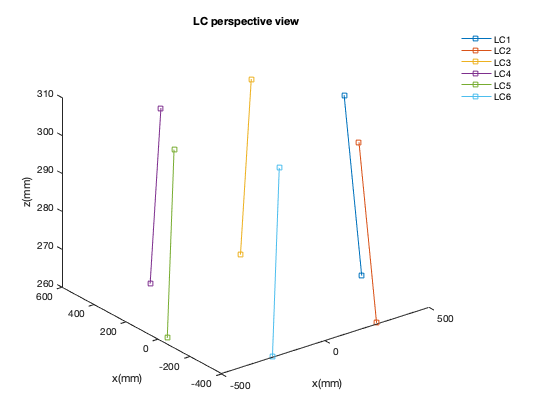

figure(2)
for k =1:2:12
    plot3(nodexyz(k:k+1,1),nodexyz(k:k+1,2),nodexyz(k:k+1,3),'s-');
    hold on;
end
legend('LC1','LC2','LC3','LC4','LC5','LC6'); legend boxoff
title('LC perspective view');
xlabel('x(mm)'); ylabel('x(mm)'); zlabel('z(mm)');
hold off;

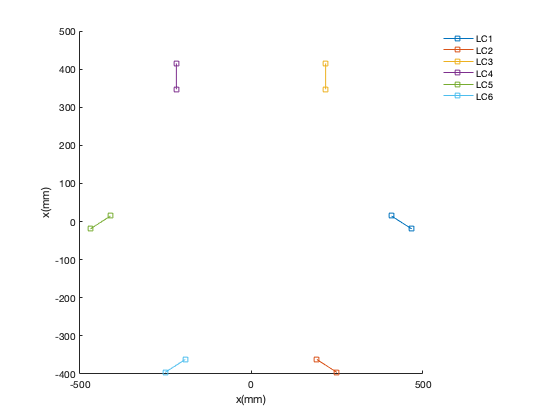


figure(3)
for k =1:2:12
    plot3(nodexyz(k:k+1,1),nodexyz(k:k+1,2),nodexyz(k:k+1,3),'s-');
    hold on;
end
axis square; view(2)
legend('LC1','LC2','LC3','LC4','LC5','LC6','Location',"bestoutside"); legend boxoff
hold off;
xlabel('x(mm)'); ylabel('x(mm)');

T1

T1 =     0.0041    0.8236    0.2887    2.2991   -1.3274    0.9385
   -0.7112   -0.4154    0.2887   -2.2991    1.3274   -0.9385
    0.7153   -0.4082    0.2887    0.0000   -2.6548   -0.9385
   -0.7153   -0.4082    0.2887    0.0000    2.6548    0.9385
   -0.0041    0.8236    0.2887    2.2991    1.3274   -0.9385
    0.7112   -0.4154    0.2887   -2.2991   -1.3274    0.9385


% fprintf("%.3g\t%.3g\t%.3g\t%.3g\t%.3g\t%.3g\n",T1);

Auxiliary function defining the load cell attachment points and the LC to rigid-body forces conversion matrix.

OBS: Function taken from [J:\DaveS\Vibration\workingGroup\TestSetup\calibration_analysis.m](matlab:open('../../../gmt-data/AHU-vib-data/TestSetup/calibration_analysis.m'))

function [nodexyz, T1] = get_lc_dt()
nodexyz = [468.1294683	-19.12730746	260.2143552;...
    409.4896035	14.7284343	308.0858232;...
    250.6294683	-395.8483581	260.2143552;...
    191.9896035	-361.9926164	308.0858232;...
    217.5	347.2641821	308.0858232;...
    217.5	414.9756656	260.2143552;...
    -217.5	347.2641821	308.0858232;...
    -217.5	414.9756656	260.2143552;...
    -409.4896035	14.7284343	308.0858232;...
    -468.1294683	-19.12730746	260.2143552;...
    -191.9896035	-361.9926164	308.0858232;...
    -250.6294683	-395.8483581	260.2143552];

meanz = mean(nodexyz(:,3));
midp = [0,0,meanz]';
T = zeros(6);
for k =1:2:12
    ii = (k-1)/2+1;
    xyz = nodexyz(k+1,:)-nodexyz(k,:);
    if(xyz(3)<0)
        xyz = -xyz;
    end
    R = 1e-3*((nodexyz(k+1,:)'+nodexyz(k,:)')/2-midp); %APPROXIMATE moment arm... need to decide on a CENTER
    T(:,ii) = [xyz'/norm(xyz); cross(R,xyz'/norm(xyz))];    
end
% sqrt(sum(T.^2,2))
T1 = inv(T);
end